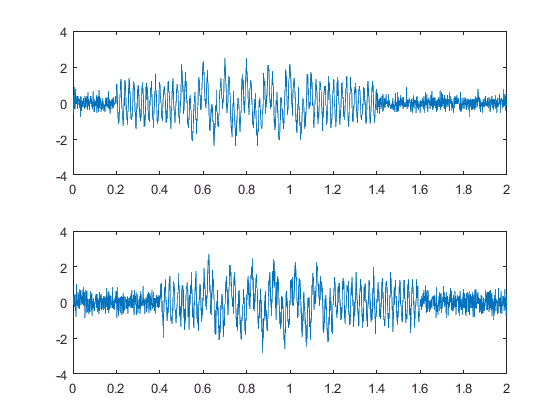

clear,close all,clc
rng default;
t = 0:0.001:2;
x = cos(2*pi*10*t).*(t>=0.5 & t<1.1)+ ...
    cos(2*pi*50*t).*(t>= 0.2 & t< 1.4)+0.25*randn(size(t));
% 10Hz, [0.5 1.1]
% 50Hz, [0.2 1.4]
% random noise
y = sin(2*pi*10*t).*(t>=0.6 & t<1.2)+...
    sin(2*pi*50*t).*(t>= 0.4 & t<1.6)+ 0.35*randn(size(t));
% 10Hz, [0.6 1.2]
% 50Hz, [0.4 1.6)
% random noise
subplot(211);plot(t, x);
subplot(212);plot(t, y);

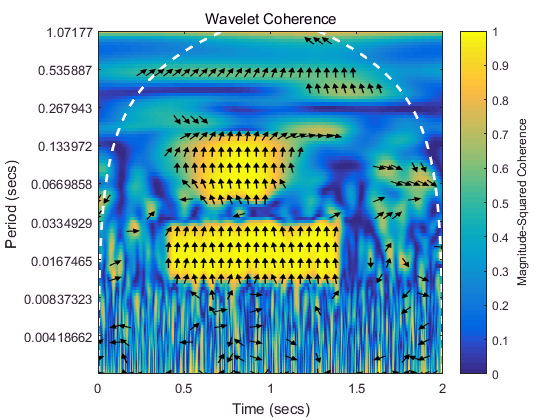

figure;
% [wcoh,~,period,coi] = wcoherence(x,y,seconds(0.001));
wcoherence(x,y,seconds(0.001))

Use the pcolor command to plot the coherence and cone of influence


% period = seconds(period);
% coi = seconds(coi);
% h = pcolor(t,log2(period),wcoh);
% h.EdgeColor = 'none';
% ax = gca;
% ytick=round(pow2(ax.YTick),3);
% ax.YTickLabel=ytick;
% ax.XLabel.String='Time';
% ax.YLabel.String='Period';
% ax.Title.String = 'Wavelet Coherence';
% hcol = colorbar;
% hcol.Label.String = 'Magnitude-Squared Coherence';
% hold on;
% plot(ax,t,log2(coi),'w--','linewidth',2);


**Effect of Sampling Frequency on Wavelet Coherence**

rng default;
t = 0:0.001:2;
x = cos(2*pi*10*t).*(t>=0.5 & t<1.1)+...
    cos(2*pi*50*t).*(t>= 0.2 & t< 1.4)+0.0*randn(size(t));
% 10Hz, [0.5 1.1]
% 50Hz, [0.2 1.4]
% random noise
y = sin(2*pi*10*t).*(t>=0.6 & t<1.2)+...
    sin(2*pi*50*t).*(t>= 0.4 & t<1.6)+ 0.0*randn(size(t));
% 10Hz, [0.6 1.2]
% 50Hz, [0.4 1.6)
% random noise
wcoherence(x,y,1000,'NumScalesToSmooth', 1);

错误使用 wcoherence
需要的 NumScalesToSmooth 应为 整数值。
出错 wcoherence>parseinputs (line 279)
    validateattributes(params.numscalestosmooth,{'numeric'},{'positive',...
出错 wcoherence (line 95)
params = parseinputs(numel(x),varargin{:});

**Effect of Number of Smoothed Scales on Wavelet Coherence**

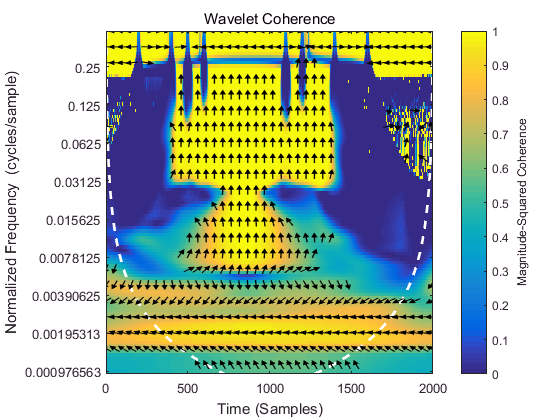

wcoherence(x, y, 'NumScalesToSmooth', 12)